clear all; close all; clc; rng(1);

## Function to be learned

g = @(p) [ ...
             sin(pi * p(1)) + 0.5 * p(2);
             cos(pi * p(2)) + 0.5 * p(1)
         ];

p = [linspace(-2, 2, 50); linspace(-2, 2, 50)];

## Neural Network Architecture

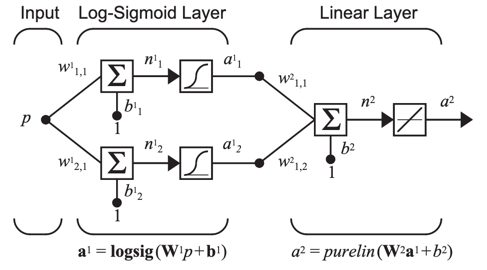

f  = {
        @(n) logsig(n)
        @(n) purelin(n)
     };
df = {
        @(n) logsig(n) .* (1 - logsig(n))
        @(n) ones(size(n))
     };

trainingData = twodi_TrainingData_Class();

for i = 1 : 1 : size(p, 2)
    trainingData.addTrainingSample("input", p(:, i), "output", g(p(:, i)) + 0.25 * randn(size(g(p(:, i)))));
end

**Visualize the data**

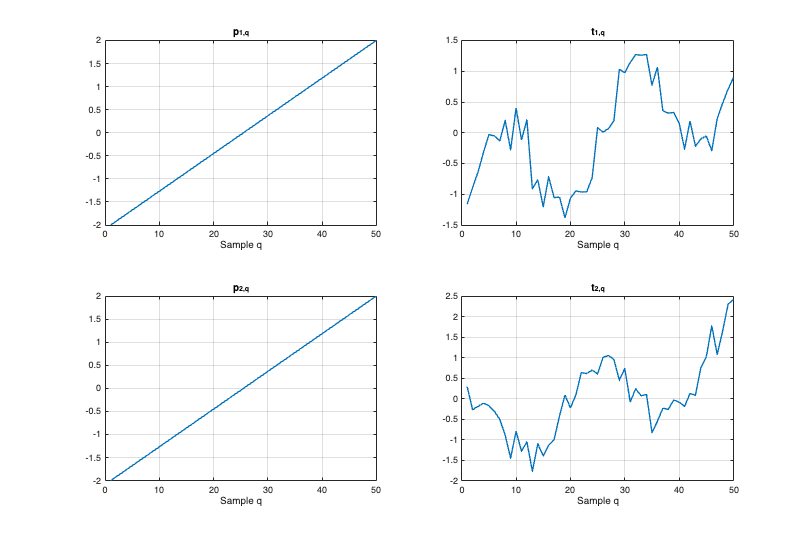

t = zeros(2, trainingData.getNrOfTrainingSamples());
p_plot = zeros(2, trainingData.getNrOfTrainingSamples());

for q = 1:trainingData.getNrOfTrainingSamples()

    [p_q, t_q] = trainingData.getTrainingSample(q);

    p_plot(:, q) = p_q;
    t(:, q)      = t_q;

end

figure('Position', [100 100 900 600]);
subplot(2,2,1); plot(1:size(p_plot,2), p_plot(1,:), 'LineWidth',1.5); grid on; xlabel('Sample q'); title('p_{1,q}');
subplot(2,2,2); plot(1:size(t,2),      t(1,:),      'LineWidth',1.5); grid on; xlabel('Sample q'); title('t_{1,q}');
subplot(2,2,3); plot(1:size(p_plot,2), p_plot(2,:), 'LineWidth',1.5); grid on; xlabel('Sample q'); title('p_{2,q}');
subplot(2,2,4); plot(1:size(t,2),      t(2,:),      'LineWidth',1.5); grid on; xlabel('Sample q'); title('t_{2,q}');

$F\left(\mathbb{x}\right)=\beta {\mathbb{v}}^T \mathbb{v}+\alpha {\mathbb{x}}^T \mathbb{x}$** instead of **$F\left(\mathbb{x}\right)={\mathbb{v}}^T \mathbb{v}$

Q = trainingData.getNrOfTrainingSamples();

NR_OF_EPOCHS = 200;

mu    = 0.01;
alpha = 0.01;
beta  = 1;

h = waitbar(0, 'Training progress...');
ITER = struct([]);
for epoch = 1 : 1 : NR_OF_EPOCHS

    ITER(epoch).network = twodi_NetworkMLP_Class(                                          ...
                                                 "nrOfLayers" , 2                        , ...
                                                 "nrOfInputs" , size(p, 1)               , ...
                                                 "nrOfNeurons", [50, size(g(p(:, 1)), 1)], ...
                                                 "actvnFcn"   , f                        , ...
                                                 "dActvnFcn"  , df                         ...
                                                );
    if(epoch >= 2)
        ITER(epoch).network.setWeigths(ITER(epoch - 1).network.getWeights);
        ITER(epoch).network.setBiases(ITER(epoch - 1).network.getBiases);
    end

    M     = ITER(epoch).network.getNrOfLayers;
    gamma = ITER(epoch).network.getNrOfPrms;
    S_M   = ITER(epoch).network.getNrOfNeurons(M);

            **Compute the Jacobian **$J=\frac{\partial \mathbb{v}}{\partial \mathbb{x}}|_{\mathbb{x}={\mathbb{x}}_k }$

    J = NaN(S_M * Q, ITER(epoch).network.getNrOfPrms);
    for q = 1 : 1 : Q

        [p_q, ~] = trainingData.getTrainingSample(q);

        J(((q - 1) * S_M + 1) : (q * S_M), :) = ITER(epoch).network.getBackprop__de_dx(p_q);
    end
    if any(isnan(J), 'all'), error('NaN detected in Jacobian J.'); end

           ** Compute the network error**

    v = NaN(S_M * Q, 1);
    for q = 1 : 1 : Q

        [p_q, t_q] = trainingData.getTrainingSample(q);
        [~  , a  ] = ITER(epoch).network.evaluate(p_q);

        v(((q - 1) * S_M + 1) : (q * S_M), 1) = t_q - a{M};
    end

**            Update of the effected usefull number of parameters**

    if(epoch >= 2)
        gamma = ITER(epoch).network.getNrOfPrms - 2 * alpha * trace((2 * beta * (J' * J) + 2 * alpha * eye(size(J, 2))) \ eye(ITER(epoch).network.getNrOfPrms));
        alpha = gamma / (2 * (ITER(epoch).network.getPrms()' * ITER(epoch).network.getPrms()));
        beta  = (Q * S_M - gamma) / (2 * (v' * v));
    end

             **Compute the performance index**

    ITER(epoch).F = beta * (v' * v) + alpha * (ITER(epoch).network.getPrms()' * ITER(epoch).network.getPrms());
    ITER(epoch).index = epoch;
    ITER(epoch).alpha = alpha;
    ITER(epoch).beta  = beta;
    ITER(epoch).gamma = gamma;

**            Levenberg-Marquardt update. Recompute the sum of squared errors using **$\mathbb{x}+\Delta \mathbb{x}$

   network_test = twodi_NetworkMLP_Class(                                          ...
                                         "nrOfLayers" , 2                        , ...
                                         "nrOfInputs" , size(p, 1)               , ...
                                         "nrOfNeurons", [50, size(g(p(:, 1)), 1)], ...
                                         "actvnFcn"   , f                        , ...
                                         "dActvnFcn"  , df                         ...
                                        );
    while(1)
        
        x       = ITER(epoch).network.getPrms();
        Hessian = beta * (J' * J) + (alpha + mu) * eye(size(J, 2));
        gradF   = beta * (J' * v) + alpha * x;

        x_new   = x - Hessian \ gradF;

        network_test.setPrms(x_new);

        v_new = NaN(S_M * Q, 1);
        for q = 1 : 1 : Q
    
            [p_q, t_q] = trainingData.getTrainingSample(q);
            [~  , a  ] = network_test.evaluate(p_q);
    
            v_new(((q - 1) * S_M + 1) : (q * S_M), 1) = t_q - a{M};
        end

        F_new = beta * (v_new' * v_new) + alpha * (x_new' * x_new);

        if(F_new < ITER(epoch).F)
            mu = mu / 10;

            ITER(epoch).network.setPrms(x_new);
            ITER(epoch).F = F_new;

            break;
        else
            mu = mu * 10;
        end
    end

    clear network_test;

            **Update progress bar**

    waitbar(epoch / NR_OF_EPOCHS, h, sprintf('Training progress: %.1f%%', 100 * epoch / NR_OF_EPOCHS));
end
close(h);

## Validation

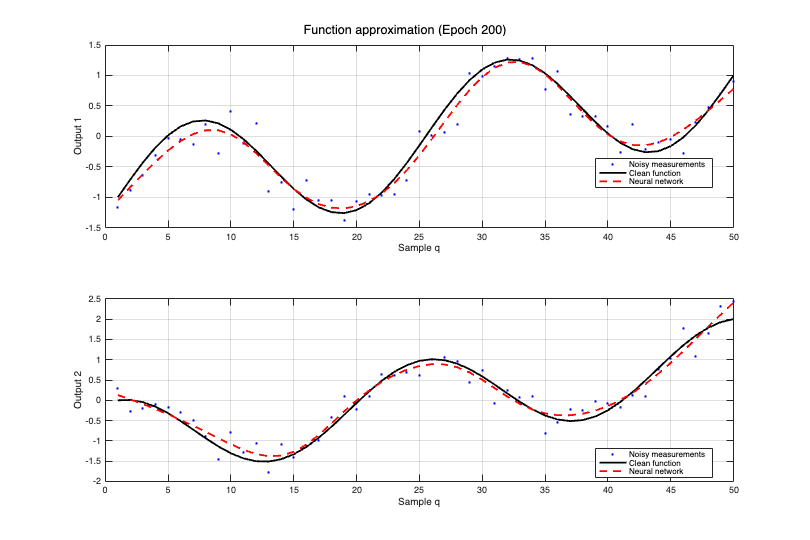

NR_OF_FRAMES = 50;

t_clean = zeros(2, Q);
t_noisy = zeros(2, Q);

for q = 1:Q

    [p_q, t_q] = trainingData.getTrainingSample(q);

    t_clean(:, q) = g(p_q);
    t_noisy(:, q) = t_q;

end

figure('Position',[100 100 900 600]);

subplot(2,1,1);
plot(1:Q, t_noisy(1,:), 'b.', 'MarkerSize', 8); hold on;
plot(1:Q, t_clean(1,:), 'k-', 'LineWidth', 2);
h1 = plot(1:Q, nan(1,Q), 'r--', 'LineWidth', 2);
grid on;
xlabel('Sample q');
ylabel('Output 1');
legend({'Noisy measurements','Clean function','Neural network'}, ...
       'Location','best');

subplot(2,1,2);
plot(1:Q, t_noisy(2,:), 'b.', 'MarkerSize', 8); hold on;
plot(1:Q, t_clean(2,:), 'k-', 'LineWidth', 2);
h2 = plot(1:Q, nan(1,Q), 'r--', 'LineWidth', 2);
grid on;
xlabel('Sample q');
ylabel('Output 2');
legend({'Noisy measurements','Clean function','Neural network'}, ...
       'Location','best');

for epoch = round(linspace(1, NR_OF_EPOCHS, NR_OF_FRAMES))

    network = ITER(epoch).network;
    y = zeros(2, Q);

    for q = 1:Q

        [p_q, ~] = trainingData.getTrainingSample(q);

        [~, a] = network.evaluate(p_q);

        y(:, q) = a{end};

    end

    set(h1, 'YData', y(1,:));
    set(h2, 'YData', y(2,:));

    sgtitle(sprintf('Function approximation (Epoch %d)', epoch));

    drawnow;
    pause(0.1);

end

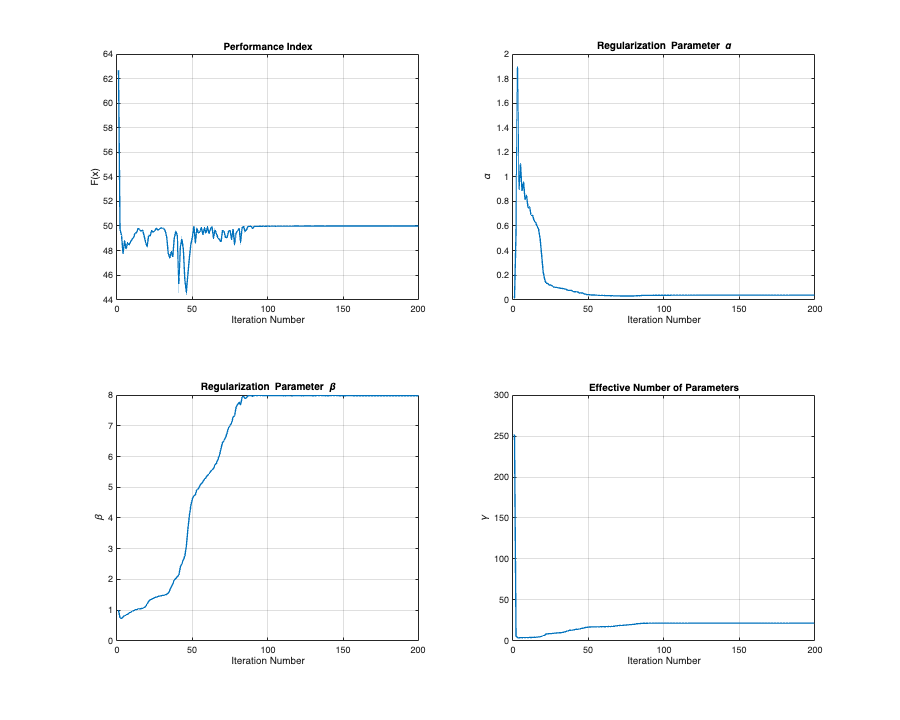

figure('Position',[100 100 1000 800]);

subplot(2,2,1)
plot([ITER.index], [ITER.F], 'LineWidth',1.5);
grid on;
xlabel('Iteration Number');
ylabel('F(x)');
title('Performance Index');

subplot(2,2,2)
plot([ITER.index], [ITER.alpha], 'LineWidth',1.5);
grid on;
xlabel('Iteration Number');
ylabel('\alpha');
title('Regularization Parameter \alpha');

subplot(2,2,3)
plot([ITER.index], [ITER.beta], 'LineWidth',1.5);
grid on;
xlabel('Iteration Number');
ylabel('\beta');
title('Regularization Parameter \beta');

subplot(2,2,4)
plot([ITER.index], [ITER.gamma], 'LineWidth',1.5);
grid on;
xlabel('Iteration Number');
ylabel('\gamma');
title('Effective Number of Parameters');